# Introducing the Week 2 Project

You've seen how to perform transfer learning on a dataset of fasteners. For the Week 2 project, you will perform transfer learning to classify the traffic signs dataset introduced in Week 1. 

For this project, you will need to:

- Prepare the traffic signs dataset

- Set your training options

- Import a pre-trained network for transfer learning. Recall that the traffic sign dataset has 9 classes.

- Train your network

- Evaluate your results

Specifically, we require that you:

- Use **ResNet-18** as the pre-trained network you'll update

- Train for **6 epochs**

% importing the pretrained network 
net = imagePretrainedNetwork("resnet18", "NumClasses",9);

% importing the training Data 
path = "D:\Workspace\DL for Computer Vision\Data\Traffic Signs\Train";
imdsSigns = imageDatastore(path, "IncludeSubfolders",true, "LabelSource","foldernames");

% Splitting the Data
[imdsTrain, imdsValidation] = splitEachLabel(imdsSigns, 0.8, "randomized");

% augmenting the data
inputSize = net.Layers(1).InputSize;
augTrain = augmentedImageDatastore(inputSize, imdsTrain);
augVal = augmentedImageDatastore(inputSize, imdsValidation);

Training the model

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:00        0.001                            2.8629
            1        1       00:00:00        0.001          3.3684                  
           50       10       00:00:23        0.001       0.0014353           0.16674
          100       20       00:00:43        0.001      0.00016773           0.12134
          150       30       00:01:04        0.001      6.9824e-05           0.11019
Training stopped: Max epochs completed


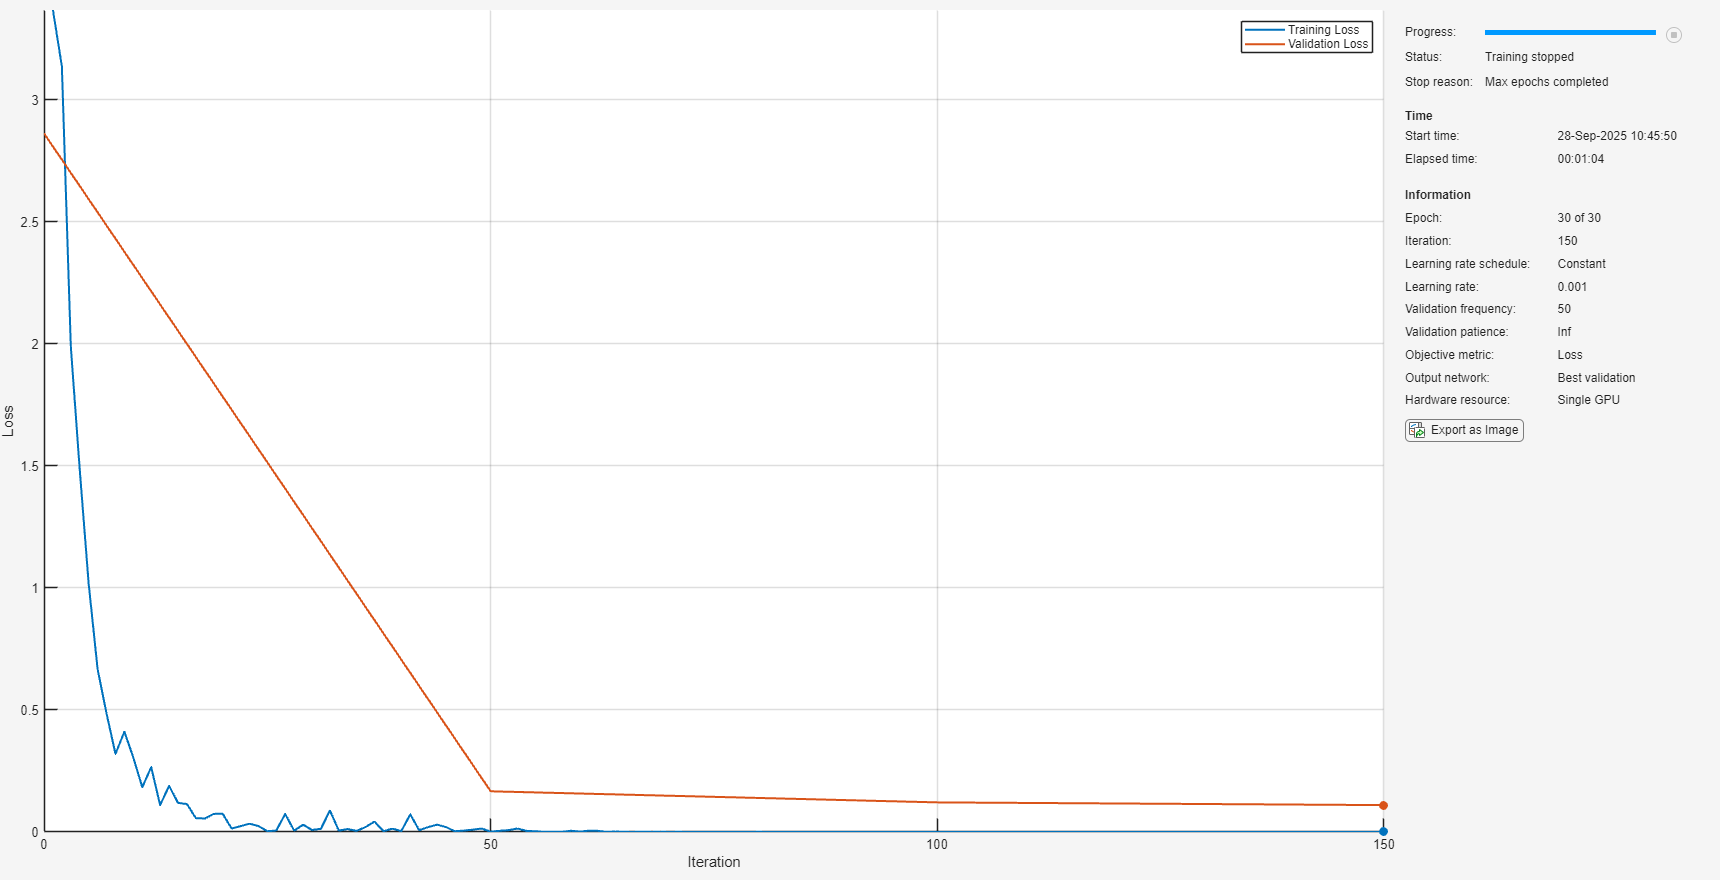

opts = trainingOptions("adam", "ValidationData",augVal, "Shuffle","every-epoch", "Plots","training-progress" ...
    , "OutputNetwork","best-validation");

resnet18TrafficSigns = trainnet(augTrain, net, "crossentropy", opts);

testPath = "D:\Workspace\DL for Computer Vision\Data\Traffic Signs\Test";
imdsTest = imageDatastore(testPath, "IncludeSubfolders",true, "LabelSource","foldernames");
augTest = augmentedImageDatastore(inputSize, imdsTest);

classNames = categories(imdsTest.Labels);

testPreds = minibatchpredict(resnet18TrafficSigns, augTest);
testPredsClasses = scores2label(testPreds, classNames);

testAccuracy = nnz(testPredsClasses == imdsTest.Labels) / length(testPredsClasses)

testAccuracy = 0.9757